clc
clear

dotq=[1;1;1;1;1;1];
ke=10;
% kp=10;
%initial value
Q=[0;0;0;0;0;0];
dotQ=[0;0;0;0;0;0];
q=[0;0;0;0;0;0];
Qy=40;
%dt
elasticdt=0.005;
plasticdt=0.005/100;

if norm(Q(:,1))-Qy>0
else
    iflag=0;
end

for i=1:4001
    if iflag==0
       q(:,i+1)=q(:,i)+dotq*elasticdt;
        Q(:,i+1)=Q(:,i)+dotq*ke*elasticdt;
                  dotQ=( Q(:,i+1)-Q(:,i))/elasticdt;
        
        if norm(Q(:,i+1))-Qy>0
            if Q(:,i+1)'*dotQ<0
                iflag=0;
                     q(:,i+1)=q(:,i)+dotq*elasticdt;
        Q(:,i+1)=Q(:,i)+dotq*ke*elasticdt;
            else
                iflag=1;
                i
                syms dt
                f=Q(:,i)+dotQ*dt;
                f1=norm(f)-Qy;
                dt1=solve(f1,dt);
                dt=double(dt1);
                   aa=find (dt<0);
                dt(aa)=[];
               q(:,i+1)=q(:,i)+dotq*dt;
        Q(:,i+1)=Q(:,i)+dotq*ke*dt;%Qton              
                elat=(i-1)*0.005+dt;
                ik=1;
            end
        end
    end
    if iflag==1 && ik==0
        q(:,i+1)=q(:,i)+dotq*elasticdt;
        Q(:,i+1)=Q(:,i)+(-Q(:,i)'*dotq*Q(:,i)*ke/(Qy*Qy)+dotq*ke)*plasticdt;
        
       
        if Q(:,i+1)'*dotQ<0
            iflag=0;
             q(:,i+1)=q(:,i)+dotq*elasticdt;
        Q(:,i+1)=Q(:,i)+dotq*ke*elasticdt;
            
        end
    end
    ik=0;
end

i = 327

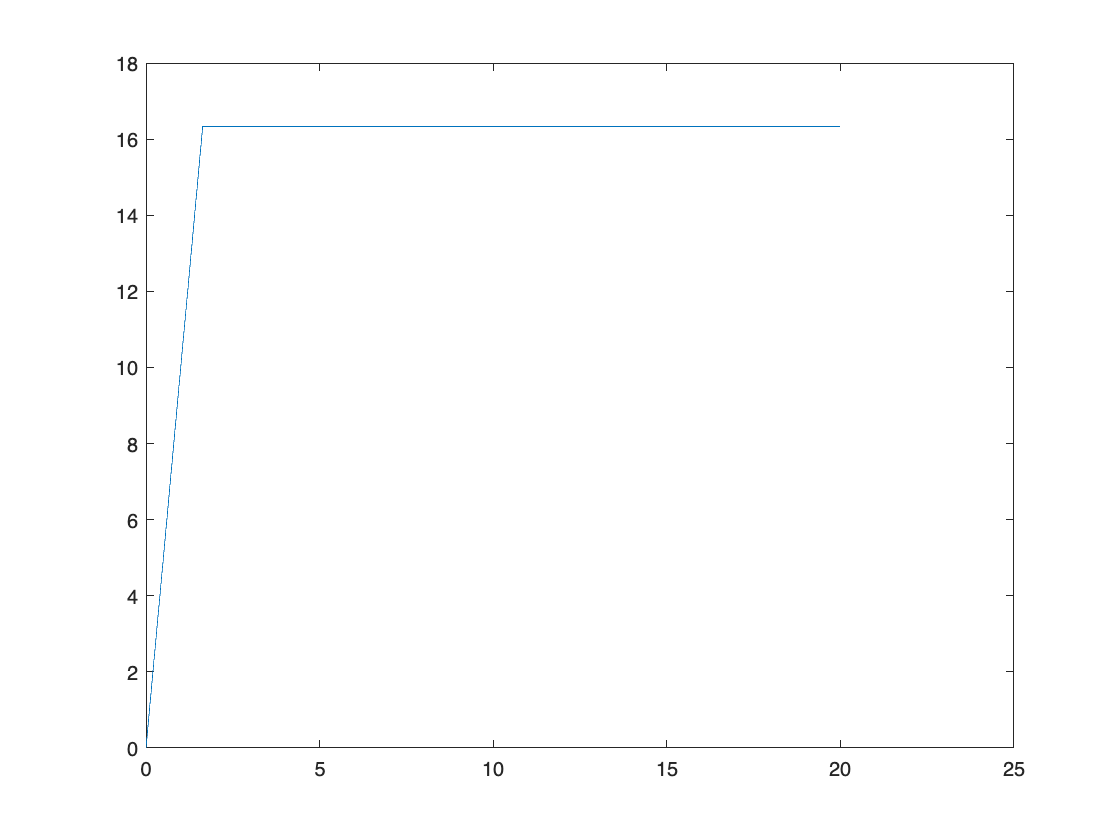

plot(q(1,:),Q(1,:))